# MXB226 Case Study Modelling an Electronic Component

## Full Storage

load full_storage;
%Solving using cholesky factorisation, then forward and backward
%substitution
A = cholesky(A);
temperatures = forward_substitution(A', b);
temperatures = backward_substitution(A, temperatures);

Visualisating the Temperature from Full Storage

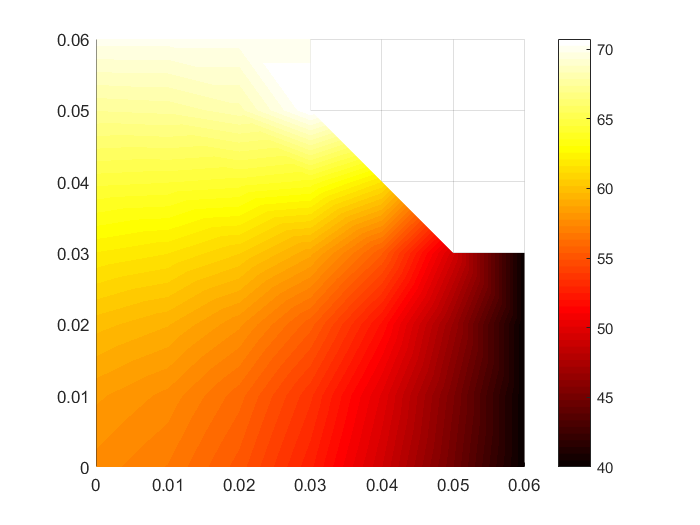

visualisation(temperatures)

## Packed Storage

load full_storage
%NOT CORRECT, NEED TO FIX FORWARD AND BACK SUBS
a = packed_storage(A);
a = Cholesky_Packed(a);
temperatures = packed_forward_substitution(a, b);
temperatures = packed_backward_substitution(a, temperatures);

Visualisating the Temperature from Packed Storage

visualisation(temperatures)

## Band Storage

%RCM Storage
load full_storage
%Create a new matrix to work with
A_RCM = A;
%create ordering vector
p= symrcm(A_RCM);
%order the A matrix and b vector according the RCM storage
A_RCM = A_RCM(p,p);
b_rcm = b(p);
reorder = reorder_vector(p);
%Create a band storage for A
A_band = band(A_RCM);
%Perform cholesky factorisation on the banded matrix
G_Band_then_chol = cholesky_band(A_band, 8);

%solve with forward substitution and then backwards substitution

temperatures = banded_forward_substitution(G_Band_then_chol, b_rcm);
temperatures = banded_backward_substitution(G_Band_then_chol, temperatures);
temperatures = temperatures(reorder);
%Visualisating the Temperature from Band Storage

Visualise the temperatures

visualisation(temperatures)

## Sparse Storage

temperatures = sparseStorage(A, b);

Visualisating the Temperature from Sparse Storage

visualisation(temperatures)

## CSR Storage

clear rb;
[r,c,v] = find(A);
[r_sorted,order] = sort(r);
c = c(order);
v = v(order);

r_current = r_sorted(1);
count = 0;
rb = 1;

for i = 1:length(r_sorted)
    count = count + 1;
    if (r_sorted(i) ~= r_current)
        rb = [rb, count];
        r_current = r_sorted(i);
    end
end

% rb ends with nz + 1, where nz is the total number of nonzero elements in A.
rb = [rb, count + 1];

n = size(A, 1);
x0 = ones(n, 1)*10;
tol = 1e-5;
maxiters = 1000;

Solve CSR Using Jacobi Method

[temperatures, converged, k, res] = jacobi_CSR(rb, c', v', b, x0, tol, maxiters);
converged

converged = logical
   1


k

k = 321

res

res =     0.8376    0.4563    0.3199    0.2639    0.2224    0.2014    0.1809    0.1692    0.1564    0.1483    0.1395    0.1333    0.1267    0.1218    0.1166    0.1124    0.1081    0.1044    0.1007    0.0974    0.0942    0.0912    0.0883    0.0855    0.0828    0.0803    0.0778    0.0754    0.0731    0.0709    0.0687    0.0666    0.0646    0.0627    0.0608    0.0589    0.0572    0.0555    0.0538    0.0522    0.0506    0.0491    0.0476    0.0462    0.0448    0.0434    0.0421    0.0409    0.0397    0.0385


Visualisating the Temperature from Jacobi CSR Storage

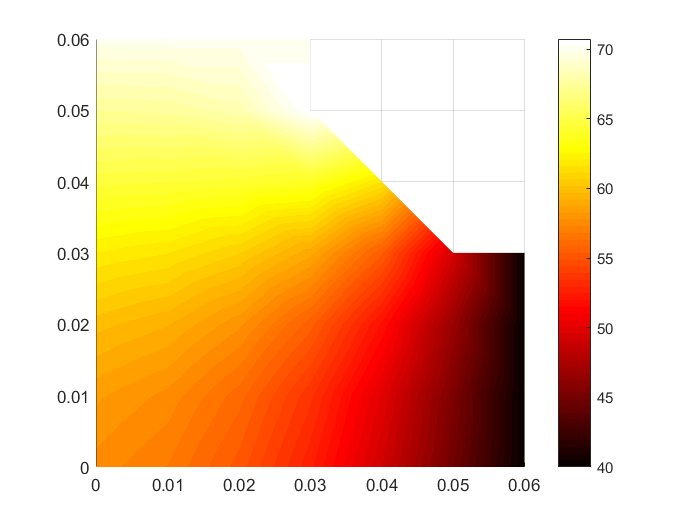

visualisation(temperatures)

Solve CSR Using Gauss Seidel Method

[temperatures, converged, k, res] = gauss_seidel_CSR(rb, c', v', b, x0, tol, maxiters);
converged

converged = logical
   1


k

k = 163

Visualisating the Temperature from Gauss Seidel CSR Storage

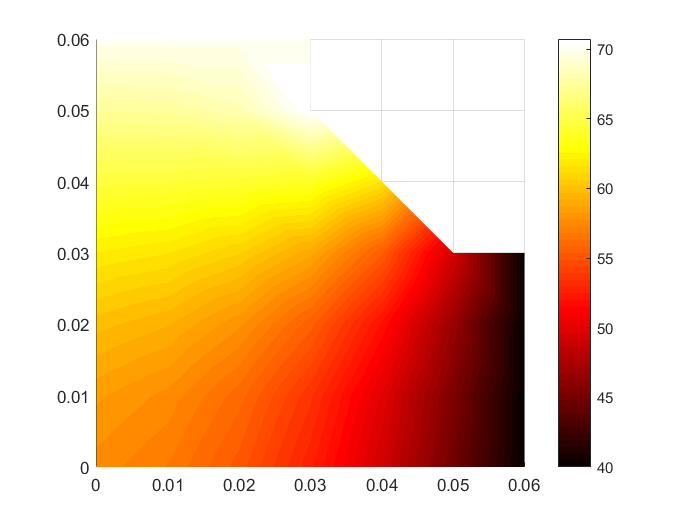

visualisation(temperatures)

Solve CSR Using Conjugate Gradient Method

[temperatures, converged, k, res] = conjugate_gradient_CSR(rb, c', v', b, x0, tol, maxiters);
converged

converged = logical
   1


k

k = 22

Visualisating the Temperature from Conjugate Gradient CSR Storage

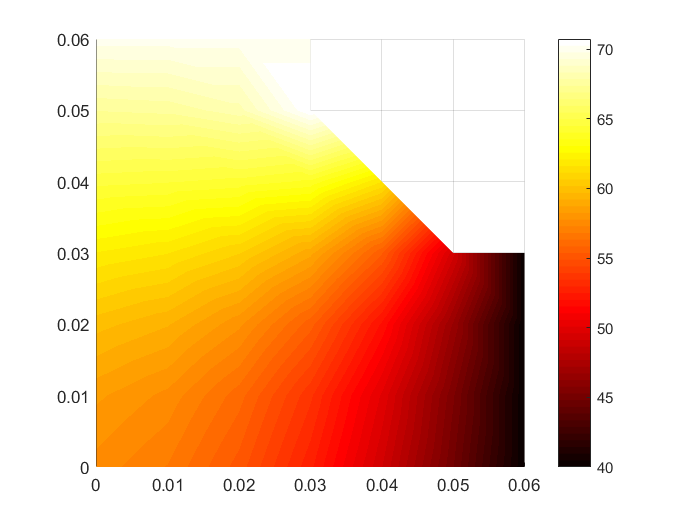

visualisation(temperatures)

Solve CSR Using SOR Method

D = diag(diag(A));
L = tril(A, -1);
U = triu(A, 1);
T_J = - (D \ (L + U));
rhoT_J = max(abs(eig(T_J)));
w = (2 /(1 + sqrt(1 - rhoT_J^2)));

[temperatures, converged, k, res] = sor_CSR(rb, c', v', b, x0, w, tol, maxiters);
converged

converged = logical
   1


k

k = 29

Visualisating the Temperature from SOR CSR Storage

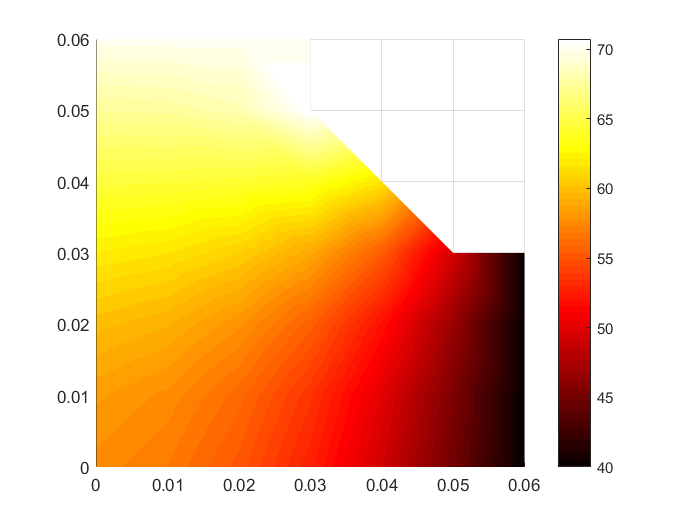

visualisation(temperatures)

## Efficiency Comparison

Bandwidth and level of fill-in for each different Node Ordering

%ffgdfh

Memory (for direct Methods), Iterations (for Iterative Methods), Runtime (Direct and Iterative), Floating Point Operations (direct and iterative).

%ffgdfh

Tolerance Required for Iterative Methods to Produce a Solution that is Visually Indistinguishable from that produced by the direct methods.

%ffgdfh

Effect of w on the rate of convergence of the SOR method.

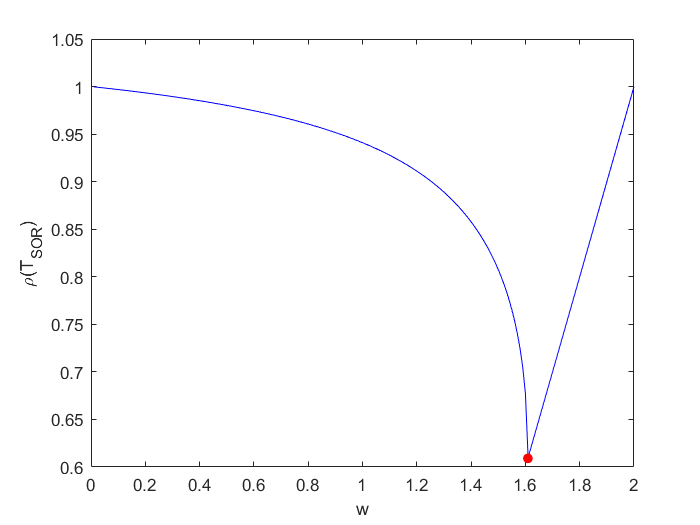

D = diag(diag(A));
L = tril(A, -1);
U = triu(A, 1);
T_J = - (D \ (L + U));
rhoT_J = max(abs(eig(T_J)));
w_opt = (2 /(1 + sqrt(1 - rhoT_J^2)));
T_SOR_opt = (D/w_opt + L) \ ((1-w_opt)/w_opt * D - U);
rhoT_SOR_opt = max(abs(eig(T_SOR_opt)));

wVec = linspace(1e-2,2,200);
rhoT_SOR = zeros(1,200);

for i = 1:200
    w = wVec(i);
    T_SOR = (D/w + L) \ ((1-w)/w * D - U);
    rhoT_SOR(i) = max(abs(eig(T_SOR)));
end

figure;
plot(wVec, rhoT_SOR, 'b')
hold on
plot(w_opt, rhoT_SOR_opt,'r.','Markersize',20);
ylabel('\rho(T_{SOR})')
xlabel('w')